# Optimise to Maxmise the Ampacity

This live script walks through the process to maximise the current carrying capacity of the conductor.  For simplicity the soil parameters have been hard coded but they can also be parametised to maximise the flexibility of the optimiser.

This second script uses the output from a Surrogate Optimisation as an input into fmincon.

## Boilerplate

kToC = 273.3;

## Bounds and Initial Conditions

### Amp Bounds

ub = 1000; % Upper bound
lb = 10; % Lower bound

### Temperature Bounds

tMax = 80; % in Celcius

% Convert to Kelvin
tMax = tMax + kToC;

### Start Point

Remeber: we can grab the surrogate estimate to start from

amp0 = solution; % Amps

## Set Up the Function Handle

minFunc = @(amp)maxTFromCurrent(amp);
nonLinConstraints = @(amp)myNonLinCon(amp, tMax);

## Optimiser

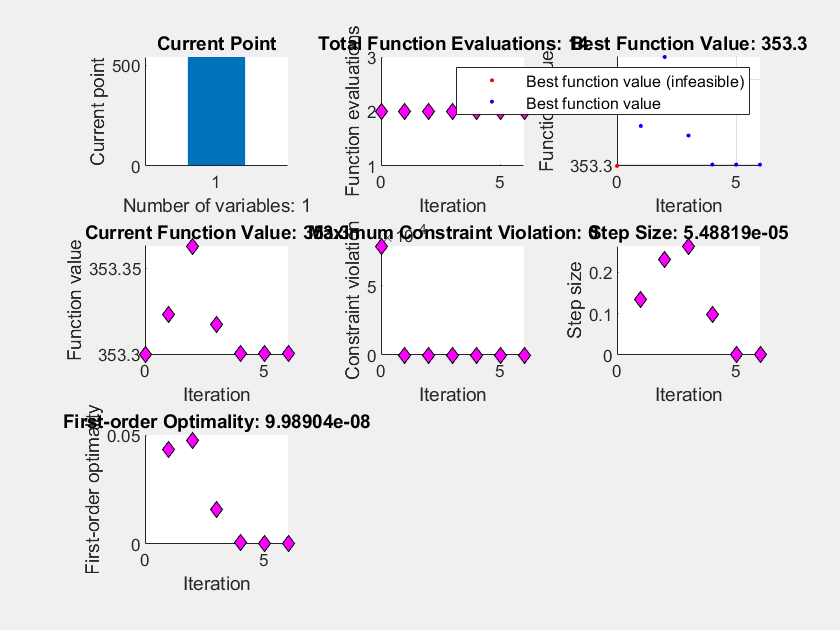

% Set nondefault solver options
options = optimoptions('fmincon','UseParallel',true,'Display','off',...
    'PlotFcn',{'optimplotx','optimplotfunccount','optimplotfvalconstr',...
    'optimplotfval','optimplotconstrviolation','optimplotstepsize',...
    'optimplotfirstorderopt'});

% Solve
[solution,objectiveValue] = fmincon(minFunc,amp0,[],[],[],[],repmat(lb,...
    size(amp0)),repmat(ub,size(amp0)),nonLinConstraints,options);


% Clear variables
clearvars options

Copyright © 2021 The MathWorks, Inc.